# Assignment 1

**Dynamical Systems and Non-Linear Dynamics**

**Giorgia Del Missier – i6292403**

b. Assume there is no stimulus, so *s = 0*. Plot the phase portait of the system:

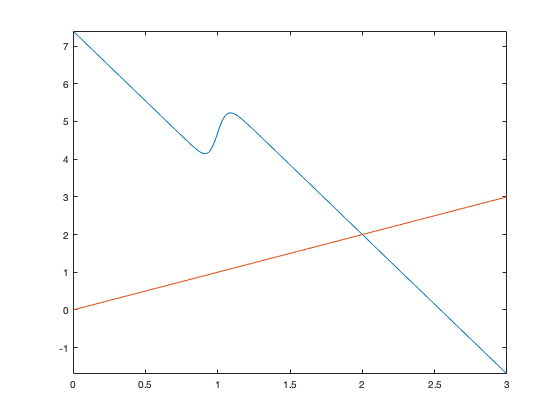

n = 30;
s =3.7;

figure()

fplot(@(x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)), [0, 3]);
hold on;
fplot(@(x) x, [0, 3]);
hold off;

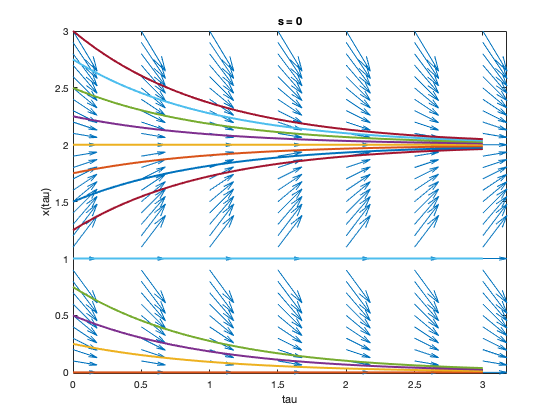

n = 30;
s = 0;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

figure()

tStep = .5;
tRange = 0:tStep:3;
xRange = 0:.1:3;
[tValues, xValues] = meshgrid(tRange, xRange);
dx = biologicalSwitch(tValues, xValues);
dt = ones(size(dx)) * tStep;
quiver(tValues, xValues, dt, dx);
axis tight;
xlabel('tau'); ylabel('x(tau)');
title('s = 0')
hold on;
% plot solution curves
xStart = 0; xStep = .25; xEnd = 3;
for x0 = xStart:xStep:xEnd 
  [tSolution, xSolution] = ode45(@(t, x) biologicalSwitch(t, x),...
      [tRange(1), tRange(end)], x0); 
  plot(tSolution, xSolution, 'lineWidth', 2);
end
hold off;

When no stimulus is present (*s = 0*), the phase portrait indicates three fixed points are present in the system: 2 stable ones, at 0 and 2, and an unstable one, at value 1. This is also clearly visible in the first figure, in which the phosphorylation by positive feedback and dephosphylation are plotted separately: the two curves intersect 3 times at the origin, at 1 and at 2.

c. Plot all the qualitatively different phase portaits that can occur for a constant stimulus *s > 0*:

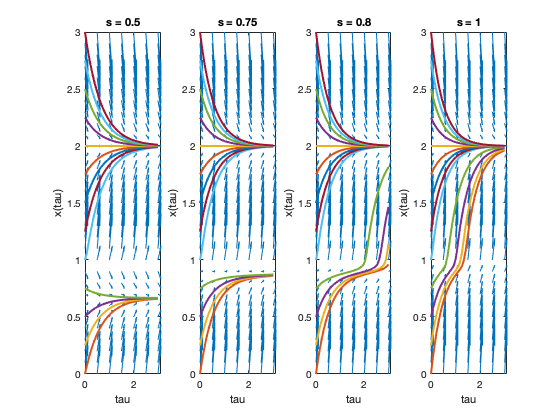

figure()

subplot(1,4,1)
s = 0.5;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

tStep = .5;
tRange = 0:tStep:3;
xRange = 0:.1:3;
[tValues, xValues] = meshgrid(tRange, xRange);
dx = biologicalSwitch(tValues, xValues);
dt = ones(size(dx)) * tStep;
quiver(tValues, xValues, dt, dx);
axis tight;
xlabel('tau'); ylabel('x(tau)');
title('s = 0.5')
hold on;
% plot solution curves
xStart = 0; xStep = .25; xEnd = 3;
for x0 = xStart:xStep:xEnd 
  [tSolution, xSolution] = ode45(@(t, x) biologicalSwitch(t, x),...
      [tRange(1), tRange(end)], x0); 
  plot(tSolution, xSolution, 'lineWidth', 2);
end
hold off;


subplot(1,4,2)
s = 0.75;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

tStep = .5;
tRange = 0:tStep:3;
xRange = 0:.1:3;
[tValues, xValues] = meshgrid(tRange, xRange);
dx = biologicalSwitch(tValues, xValues);
dt = ones(size(dx)) * tStep;
quiver(tValues, xValues, dt, dx);
axis tight;
xlabel('tau'); ylabel('x(tau)');
title('s = 0.75')
hold on;
% plot solution curves
xStart = 0; xStep = .25; xEnd = 3;
for x0 = xStart:xStep:xEnd 
  [tSolution, xSolution] = ode45(@(t, x) biologicalSwitch(t, x),...
      [tRange(1), tRange(end)], x0); 
  plot(tSolution, xSolution, 'lineWidth', 2);
end
hold off;

subplot(1,4,3)
s = 0.8;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

tStep = .5;
tRange = 0:tStep:3;
xRange = 0:.1:3;
[tValues, xValues] = meshgrid(tRange, xRange);
dx = biologicalSwitch(tValues, xValues);
dt = ones(size(dx)) * tStep;
quiver(tValues, xValues, dt, dx);
axis tight;
xlabel('tau'); ylabel('x(tau)');
title('s = 0.8')
hold on;
% plot solution curves
xStart = 0; xStep = .25; xEnd = 3;
for x0 = xStart:xStep:xEnd 
  [tSolution, xSolution] = ode45(@(t, x) biologicalSwitch(t, x),...
      [tRange(1), tRange(end)], x0); 
  plot(tSolution, xSolution, 'lineWidth', 2);
end
hold off;


subplot(1,4,4)
s = 1;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

tStep = .5;
tRange = 0:tStep:3;
xRange = 0:.1:3;
[tValues, xValues] = meshgrid(tRange, xRange);
dx = biologicalSwitch(tValues, xValues);
dt = ones(size(dx)) * tStep;
quiver(tValues, xValues, dt, dx);
axis tight;
xlabel('tau'); ylabel('x(tau)');
title('s = 1')
hold on;
% plot solution curves
xStart = 0; xStep = .25; xEnd = 3;
for x0 = xStart:xStep:xEnd 
  [tSolution, xSolution] = ode45(@(t, x) biologicalSwitch(t, x),...
      [tRange(1), tRange(end)], x0); 
  plot(tSolution, xSolution, 'lineWidth', 2);
end
hold off;

In the figure above, the occurrence of a saddle-node bifucarcation in the system is illustrated: by varying the value of s, the two fixed points at the origin and at 1 slowly move towards each other, collide and annhiliate, leaving as only fixed stable point the one at value 2. 

d. Taking into account the behavior of the fixed points that you calculated in part b., plot the bifurcation diagram of the system for increasing stimulus *s:*

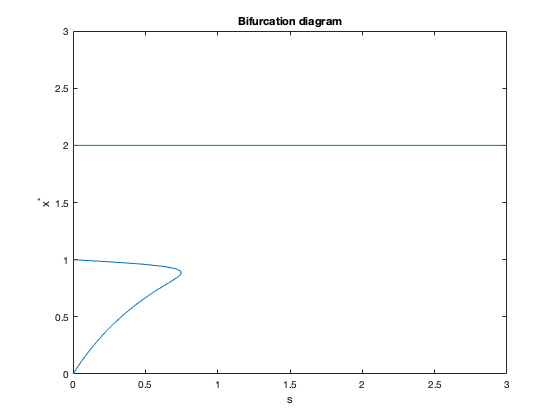

figure()

fimplicit(@(s, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x, [0, 3]);
xlabel('s'); ylabel('x^*')
title('Bifurcation diagram')

The bifurcation diagram above is in accordance with the phase portraits shown above: a stable fixed point is always present at value 2. The two fixed points at 0 and 1 when *s = 0*, instead, collide and disappear at a value of *s* comprised between 0.75 and 0.8.

e. Show that the system is *irreversible* in the following sense: if the cell starts with no phosphorylated proteins and no stimulus, then the protein activates if a sufficiently large stimulus is applied - but it does *not* deactivate if *s* is later decreased back to 0.

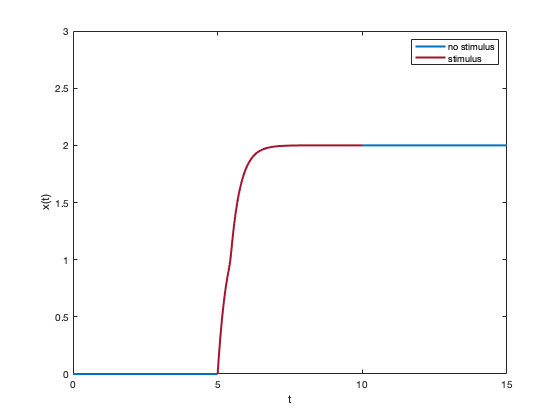

figure()

s = 0;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

x0 = 0;
y0 = 0;
[t, trajectory] = ode45(biologicalSwitch, [0,5], [x0;y0]);
plot(t, trajectory(:, 1), 'Color', '#0072BD', 'lineWidth', 2, 'displayname', 'trajectory');
hold on

s = 2;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

x0 = trajectory(end, 1);
y0 = trajectory(end, 2);
[t, trajectory] = ode45(biologicalSwitch, [5,10], [x0;y0]);
plot(t, trajectory(:, 1), 'Color', '#A2142F', 'lineWidth', 2, 'displayname', 'trajectory');
hold on

s = 0;
biologicalSwitch = @(tau, x) s .* (2-x) + 2 .* (x.^n) ./ (1 + (x.^n)) - x;

x0 = trajectory(end, 1);
y0 = trajectory(end, 2);
[t, trajectory] = ode45(biologicalSwitch, [10,15], [x0;y0]);
plot(t, trajectory(:, 1), 'Color', '#0072BD', 'lineWidth', 2, 'displayname', 'trajectory');
ylim([0 3])
legend('no stimulus', 'stimulus')
xlabel('t'); ylabel('x(t)')
hold off

f. Repeat the anaylsis above, but this time for a value of beta << kdAT. What happens with the reversibility in this case?

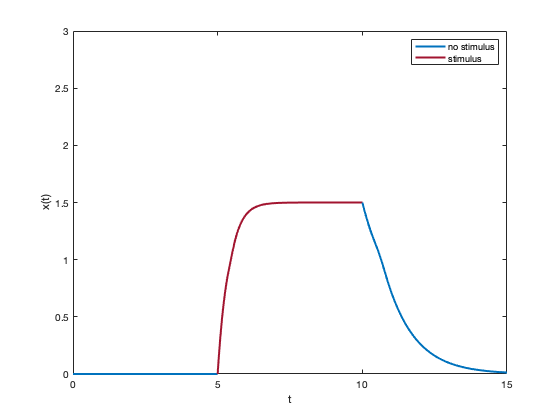

figure()

s = 0;
biologicalSwitch = @(tau, x) s .* (2-x) + 0.5 .* (x.^n) ./ (1 + (x.^n)) - x;

x0 = 0;
y0 = 0;
[t, trajectory] = ode45(biologicalSwitch, [0,5], [x0;y0]);
plot(t, trajectory(:, 1), 'Color', '#0072BD', 'lineWidth', 2, 'displayname', 'trajectory');
hold on

s = 2;
biologicalSwitch = @(tau, x) s .* (2-x) + 0.5 .* (x.^n) ./ (1 + (x.^n)) - x;

x0 = trajectory(end, 1);
y0 = trajectory(end, 2);
[t, trajectory] = ode45(biologicalSwitch, [5,10], [x0;y0]);
plot(t, trajectory(:, 1), 'Color', '#A2142F', 'lineWidth', 2, 'displayname', 'trajectory');

hold on
s = 0;
biologicalSwitch = @(tau, x) s .* (2-x) + 0.5 .* (x.^n) ./ (1 + (x.^n)) - x;

x0 = trajectory(end, 1);
y0 = trajectory(end, 2);
[t, trajectory] = ode45(biologicalSwitch, [10,15], [x0;y0]);
plot(t, trajectory(:, 1), 'Color', '#0072BD', 'lineWidth', 2, 'displayname', 'trajectory');
ylim([0 3])
legend('no stimulus', 'stimulus')
xlabel('t'); ylabel('x(t)')
hold off